# How photons become electrons and preserve the Poisson distribution

Physicists tell us that for a constant light source, the number of photons arriving at a pixel will be random.  In 1909, considering the properties of light, Einstein analyzed the randomness of the light energy in a small volume of a blackbody radiator.  He concluded that the number of photons follows the Poisson distribution, a mathematical formula that was . Only a subset of the incident photons generate an electron. The number of electrons will also be a random number, called 'shot noise'.   The shot noise is also Poisson distributed. To see why, read the script.

## The Poisson distribution

The Poisson distribution describes the statistics of a series of 'events'. For light an event is the arrival of a photon. 

The defining property of a Poisson distribution is that the chance of an event is the same at each small interval of time. 

Suppose that for each small unit of time, $\delta T$ the probability that a photon will arrive is constant, $\rho$. 

deltaT    = 1e-6;     % A microsecond
rho       = 1e-4;     % Chance of a photon in deltaT
T = deltaT:deltaT:1;  % Time samples over 1 sec

We can simulate the probably of an event happening or not using binomial distribution.  In this case we have one million short time events, and at each event the chance is 1 in 10,000.

Here is a plot with a line at each moments when there is (1) or is not (0) a photon.

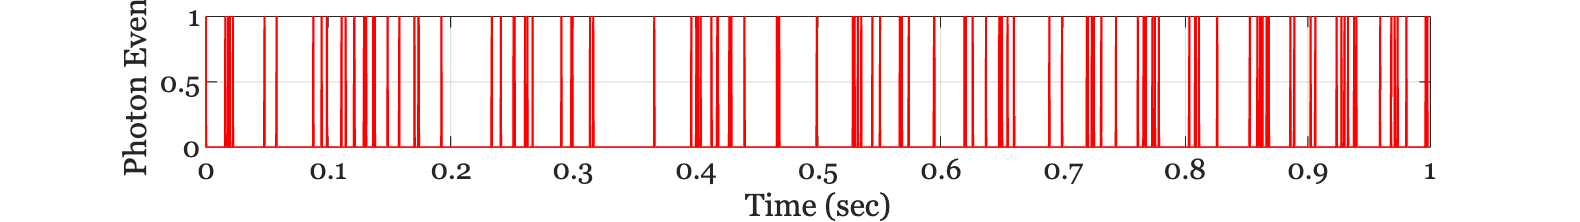

photons = binornd(1,rho,length(T),1);  % The binomial random distribution
f = ieNewGraphWin; 
plot(T,photons);
set(f,'Position',[100 100 256 64]);
xlabel('Time (sec)'); ylabel('Photon Event'); grid on

fprintf('In a second, there were %d photons\n',sum(photons));

In a second, there were 116 photons


## Photon to electron conversion

At the sensor, an event is when a photon creates an electron. For a CMOS or CCD image sensor, each photon turns into one electron or no electrons.  

Suppose the probability of a photon generating an electron is $\epsilon$.  Let's set epsilon to one half, as an example.

epsilon = 0.5;

The probability of conversion is the same whenever the photon arrives. Here is the probability of the conversion, which is also a Poisson distribution.

eConversion = binornd(1,epsilon,length(T),1);

This is not worth plotting because with $\epsilon$ so large.  The graph of eConversion will just look like a solid red square.

## The distribution of electrons

We will have an electron in the interval $\delta T$ if 

- There is a photon in that interval, and 

- The electron conversion value is 1.

The probability is the same in each little time interval, and thus the whole calculation is Poisson.

electrons = photons .* eConversion;

Here is a plot of the electrons.  This is a subset of the times when there is a photon

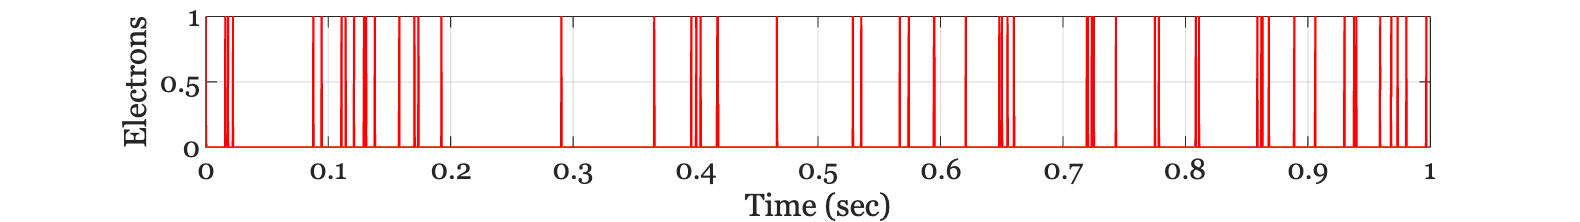

f = ieNewGraphWin; plot(T,electrons);
set(f,'Position',[100 100 256 64]);
xlabel('Time (sec)'); ylabel('Electrons'); grid on

fprintf('Combining photons with conversion likelihood, there were %d electrons\n',sum(electrons));

Combining photons with conversion likelihood, there were 59 electrons


## Equivalent calculation

We do not have to do the calculation in two steps.  The calculation would be the same distribution if we combine the two probabilities up front. 

electrons2 = binornd(1,rho*epsilon,length(T),1);

This produces the same results as doing the calculation in two steps.

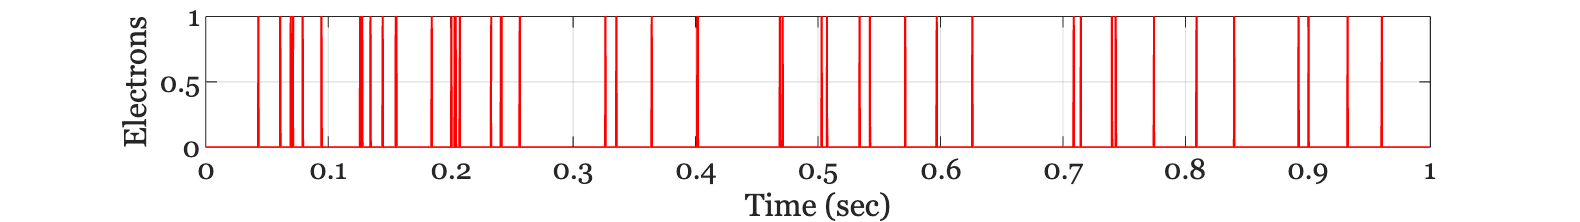

f = ieNewGraphWin; plot(T,electrons2);
set(f,'Position',[100 100 256 64]);
xlabel('Time (sec)');
ylabel('Electrons'); grid on

fprintf('The alternative calculation - use the binomial with the combined probabilities.\nThere were %d electrons\n',sum(electrons));

The alternative calculation - use the binomial with the combined probabilities.
There were 59 electrons


*ChatGPT: Which physicist first reported that the number of photons arriving at a detector from a constant light source follows the Poisson distribution?  Was it Planck?  *

**Einstein’s 1909 Fluctuation Argument: Evidence for Wave-Particle Duality**

In 1909, Albert Einstein extended his quantum theory of light by analyzing **energy fluctuations** in blackbody radiation. He considered a small subvolume of a cavity at thermal equilibrium and calculated how much the energy in that subvolume fluctuated around its mean value. Starting from thermodynamic considerations, he derived the variance in energy and found that it contained two distinct contributions:His result revealed two distinct contributions


$$\langle (\Delta E)^2 \rangle =h\nu \langle n\rangle +\langle n \rangle^2$$


where $n$ is the average number of photons with frequency $\nu$ , and $h$ is Planck’s constant. 

- The first term, **proportional to **$\langle n \rangle$, reflects the statistical fluctuations expected from **independent particles**—like molecules in a gas or photons in a beam. This corresponds to a **Poisson distribution** in photon number.

- The second term, **proportional to **$\langle n \rangle^2$, arises from **wave interference** effects, similar to intensity fluctuations in classical wave optics (e.g., speckle or diffraction patterns).

Einstein interpreted this result as evidence that light cannot be described purely as a wave or purely as a particle—it exhibits features of both, depending on the observable in question. This was an early and striking hint of **wave-particle duality**, decades before the full development of quantum electrodynamics.

**Poisson Statistics**

A Poisson distribution describes the number of random, independent events (like photons arriving at a detector) within a fixed interval. The probability of detecting nn photons when the average rate is λ\lambda is:


$$P(n) = \frac{\lambda^n e^{-\lambda}}{n!}$$


Einstein’s fluctuation term $h\nu \langle n \rangle$ is the hallmark of Poisson statistics.